X =          0
   -0.0017
   -0.0069
   -0.0155
   -0.0275
   -0.0429
   -0.0617
   -0.0838
   -0.1093
   -0.1381


Y =          0
    0.1000
    0.1999
    0.2995
    0.3988
    0.4976
    0.5959
    0.6934
    0.7901
    0.8859


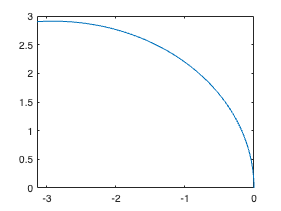

slope = 0.0619

temp = size(track);
sectors = temp(1);
init_vector = [2.91, 0];
gradient_vector = [0, 0];
step = 0.1;
heading = 0;

for j = 1:sectors
    left_or_right = track(j,1);
    if left_or_right ~= 0
        radius = track(j,2);
        arc_length = track(j,3);
        init_vector = [-radius * left_or_right, 0];
        vectors = zeros(ceil(arc_length / step), 2);
        theta = asin(step/radius);
        heading = heading + theta * ceil(arc_length/step);
        rotate_matrix = [cos(theta), -sin(theta); sin(theta), cos(theta)];
        vectors(1,:) = init_vector;
    
        for i = 2:ceil(arc_length/step)
            vectors(i,:) = (rotate_matrix*vectors(i - 1,:)');
        end
    
        for i = 1:ceil(arc_length/step)
            vectors(i,:) = vectors(i,:) - init_vector;
        end
    
        init_vector = vectors(ceil(arc_length/step),:);
        gradient_vector = vectors(ceil(arc_length/step) - 1,:);
        
        X = vectors(:,1)
        Y = vectors(:,2)
        plot(X, Y);
    else
        slope = (init_vector(2) - gradient_vector(2))/(init_vector(1) - gradient_vector(1))
        
    end
end